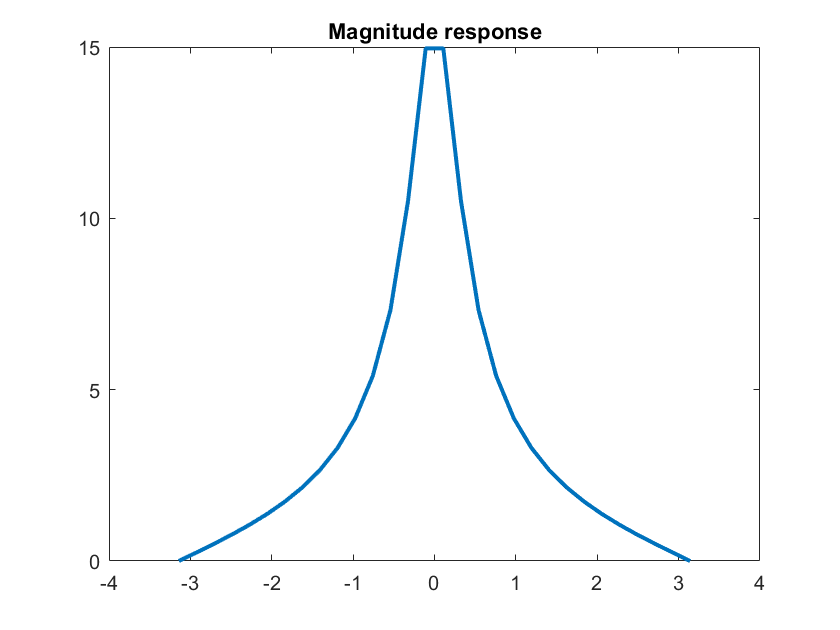

%Designing a 3 tap filter in discrete domain


w = linspace(-pi,pi,30); %DTFT periodic with 2pi
h = [1 -1 0 2]; %filter with 3 taps at n=0, n=1 and n=2

%H(w)= sum_n h[n]e^(-jwn) = h[0] +h[1]e^(-jw)+h[2]e^(-2jw)    DTFT

B = h;
A = [1 -1.75 1.25 -3/8];
[H,W] = freqz(B,A,w);
abs(H);
[phaseH,W] = phasez(B,A,w);

figure
plot(w,abs(H),'linewidth',2)
title('Magnitude response')

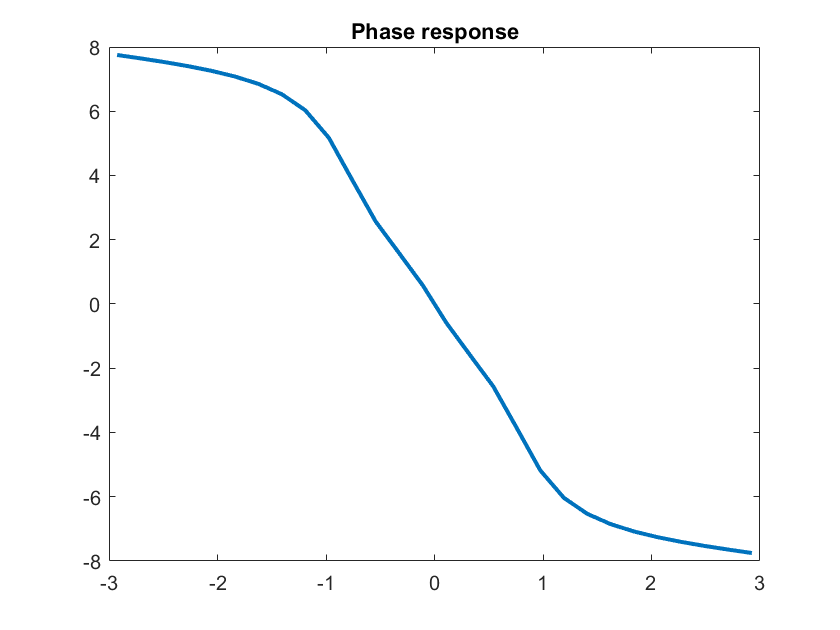



figure
plot(w,phaseH,'linewidth',2)
title('Phase response')


help freqz

 freqz Frequency response of digital filter
    [H,W] = freqz(B,A,N) returns the N-point complex frequency response
    vector H and the N-point frequency vector W in radians/sample of
    the filter:
 
                jw               -jw              -jmw
         jw  B(e)    b(1) + b(2)e + .... + b(m+1)e
      H(e) = ---- = ------------------------------------
                jw               -jw              -jnw
             A(e)    a(1) + a(2)e + .... + a(n+1)e
 
    given numerator and denominator coefficients in vectors B and A.
 
    [H,W] = freqz(SOS,N) returns the N-point complex frequency response
    given the second order sections matrix SOS. SOS is a Kx6 matrix, where
    the number of sections, K, must be greater than or equal to 2. Each row
    of SOS corresponds to the coefficients of a second order filter. From
    the transfer function displayed above, the ith row of the SOS matrix
    corresponds to [bi(1) bi(2) bi


%% DFT vs DTFT

%Example DTFT we computed
w = linspace(0,2*pi,200);
DTFT = exp(-2*j*w).*sin(5*w/2)./sin(w/2);

plot(w,abs(DTFT),'linewidth',2);

%take length 10 DFT
N = 10; %vs 100 larger period
x = [ones(1,5) zeros(1,N-5)];
x

x =      1     1     1     1     1     0     0     0     0     0


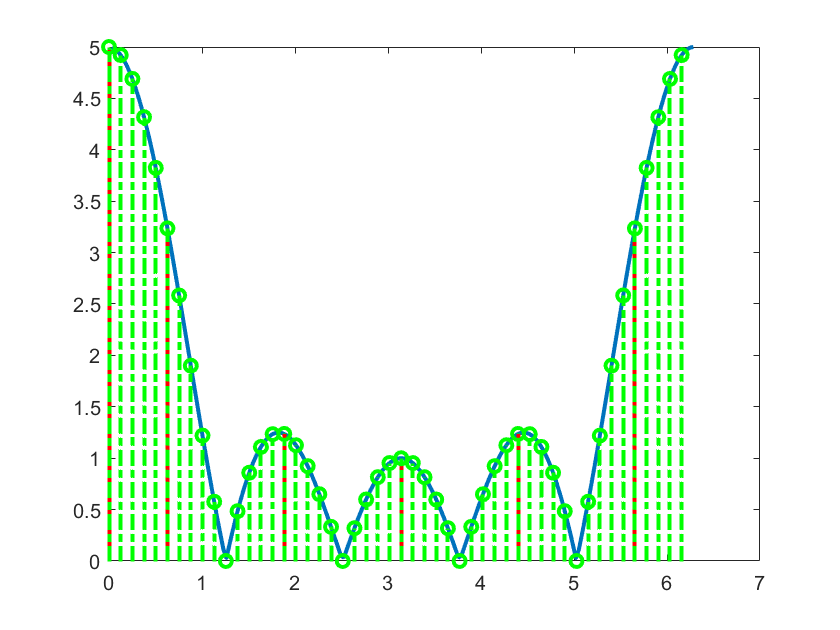

w_s = 2*pi/N*[0:N-1];
DFT = fft(x);
hold on
stem(w_s,abs(DFT),'-r','linewidth',2)

%or use fft(x,N): N-point FFT
hold on
N = 50;
w_s = 2*pi/N*[0:N-1];
stem(w_s,abs(fft(x,N)),'-.g','linewidth',2)


%take length 16 DFT
N = 16;
x = [ones(1,N)];
x
w_s = 2*pi/N*[0:N-1];
DFT = fft(x);
hold on
stem(w_s,abs(DFT),'-r','linewidth',2)

%or use fft(x,N): N-point FFT
hold on
N = 16;
w_s = 2*pi/N*[0:N-1];
stem(w_s,abs(fft(x,16)),'-.r','linewidth',2)